Preliminary Analysis

Authors: Aaron Fryzel (af3285), Zachary Heffernan (zh438), Danielle Shoshany (ds3476) - 20240205

%Load the data
raw = loaddataset();

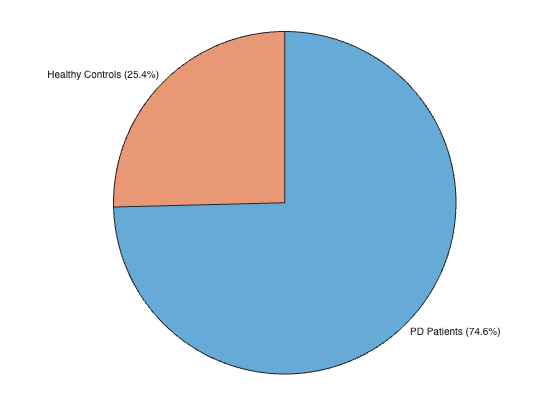

%For classification problems, report target class distribution using a pie-chart
%ahmet: Do not hardcode "755" unless you have a good reason to. If you want
%to use the last column, use "end" or get the size (R,C) of the matrix and
%use that.
n = table2array([sum(raw(:,755) == 1); sum(raw(:,755) == 0)]);
Class = ["PD Patients"; "Healthy Controls"];
piechart(n, Class);

%For each attribute, report in a tabular format (one row for each attribute): The minimum value, The maximum value, Average value, Standard deviation, Correlation with the goal/target/classification attribute.

%If there are more than 20 attributes, list only the top 10 most correlated with the goal attribute.
tmp = corrcoef(table2array(raw));
[Correlation, I] = maxk(tmp(1:end-1,end), 10);

%Find stats values
Minimum = min(raw(:,I));
Maximum = max(raw(:,I));
Average = mean(raw(:,I));
Standard_Deviation = std(raw(:,I));
Correlation = array2table(Correlation');

%Generate table
Correlation.Properties.VariableNames = Minimum.Properties.VariableNames;
t = [Minimum; Maximum; Average; Standard_Deviation; Correlation];
t.Properties.RowNames = {'Minimum', 'Maximum', 'Average', 'Standard Deviation', 'Correlation'}

t = 5×10 table
                          mean_MFCC_2nd_coef    tqwt_minValue_dec_12    tqwt_minValue_dec_11    tqwt_minValue_dec_13    std_9th_delta_delta    std_8th_delta_delta    std_7th_delta_delta    std_6th_delta_delta    std_8th_delta    std_10th_delta_delta
                          __________________    ____________________    ____________________    ____________________    ___________________    ___________________    ___________________    ___________________    _____________    ____________________

    Minimum                    -3.5566                 -0.65834                -0.39793                 -1.1416              0.

%ahmet: TODO: the table is not well-formatted, transpose it to use the fewer-sized dimension
%(min,max,etc.) as columns.